%% Modified Newton Method with checkpoints and plot
% Save this file as `modified_newton_live_script.m` and open it in MATLAB.
% The section breaks (%%) make it easy to run one step at a time.
% Each section includes a pause so you can write down observations before continuing.

clear; clc;
format compact;

%% Problem definition
% Change f, x0, or the symbols here to reuse the script on another problem.
syms x1 x2 real
f = (x1-1)^2 + 2*x2^2;

x0 = [3; 1];
maxIter = 20;
tolGrad  = 1e-10;

fprintf('Objective function f(x):\n');

Objective function f(x):


disp(f)

$${\left(x_{1}-1\right)}^{2}+2\,{x_{2}}^{2}$$

fprintf('Initial point x0 = [%.6g, %.6g]^T\n', x0(1), x0(2));

Initial point x0 = [3, 1]^T



%% Symbolic gradient and Hessian
c = gradient(f, [x1, x2]);
H = hessian(f, [x1, x2]);

fprintf('\nSymbolic gradient c(x):\n');


Symbolic gradient c(x):


disp(c)

$$\left(\begin{array}{c} 2\,x_{1}-2\\ 4\,x_{2} \end{array}\right)$$

fprintf('Symbolic Hessian H(x):\n');

Symbolic Hessian H(x):


disp(H)

$$\left(\begin{array}{cc} 2 & 0\\ 0 & 4 \end{array}\right)$$


c0 = double(subs(c, [x1 x2], x0.'));
H0 = double(subs(H, [x1 x2], x0.'));

fprintf('Gradient at x0:\n');

Gradient at x0:


disp(c0)

     4
     4


fprintf('Hessian at x0:\n');

Hessian at x0:


disp(H0)

     2     0
     0     4



%% Check Hessian definiteness
[eVecs, eVals] = eig(H0); %#ok<ASGLU>
lam = diag(eVals);

fprintf('\nEigenvalues of H0:\n');


Eigenvalues of H0:


disp(lam)

     2
     4



if all(lam > 0)
    disp('Hessian is positive definite.');
elseif all(lam < 0)
    disp('Hessian is negative definite.');
elseif all(lam >= 0)
    disp('Hessian is positive semidefinite.');
elseif all(lam <= 0)
    disp('Hessian is negative semidefinite.');
else
    disp('Hessian is indefinite.');
end

Hessian is positive definite.



%% Compute the modified Newton direction
% For a positive definite Hessian, the Newton direction is a descent direction.
% Use the backslash operator instead of inv(H0) for numerical stability.
d = -H0 \ c0;

fprintf('\nSearch direction d:\n');


Search direction d:


disp(d)

    -2
    -1



isDescent = (c0.' * d) < 0;
fprintf('c(x0)^T d = %.12g\n', c0.' * d);

c(x0)^T d = -12


if isDescent
    disp('This is a descent direction.');
else
    disp('This is NOT a descent direction.');
end

This is a descent direction.



%% Exact line search along the direction
syms alpha real
xAlpha = x0 + alpha*d;
fAlpha = simplify(subs(f, [x1 x2], xAlpha.'));
dfAlpha = simplify(diff(fAlpha, alpha));
alphaStar = solve(dfAlpha == 0, alpha);
alphaStar = double(alphaStar);

fprintf('\nLine search function f(alpha):\n');


Line search function f(alpha):


disp(fAlpha)

$$6\,{\left(\alpha -1\right)}^{2}$$

fprintf('Derivative df/dalpha:\n');

Derivative df/dalpha:


disp(dfAlpha)

$$12\,\alpha -12$$

fprintf('Candidate step size alpha*:\n');

Candidate step size alpha*:


disp(alphaStar)

     1



% If multiple roots appear, choose the real one closest to positive.
alphaStar = alphaStar(isreal(alphaStar));
alphaStar = alphaStar(alphaStar >= 0);
if isempty(alphaStar)
    error('No nonnegative real step size found from the line search.');
end
alphaStar = alphaStar(1);

%% Update the iterate
x1_new = x0 + alphaStar * d;
c1 = double(subs(c, [x1 x2], x1_new.'));
H1 = double(subs(H, [x1 x2], x1_new.'));

fprintf('\nNew iterate x1:\n');


New iterate x1:


disp(x1_new)

     1
     0


fprintf('Gradient at x1:\n');

Gradient at x1:


disp(c1)

     0
     0


fprintf('Objective value at x1: %.12g\n', double(subs(f, [x1 x2], x1_new.')))

Objective value at x1: 0


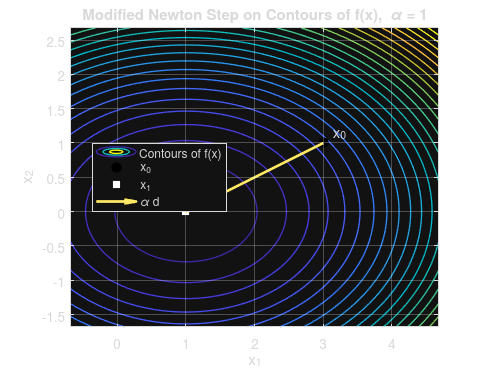


%% Plot objective contours and modified Newton step
% This plot auto-scales around x0 and x1_new, so it stays readable for
% different functions and step sizes.

fHandle = matlabFunction(f, 'Vars', [x1, x2]);

pts = [x0, x1_new];
xmin = min(pts(1,:)); xmax = max(pts(1,:));
ymin = min(pts(2,:)); ymax = max(pts(2,:));

dx = xmax - xmin;
dy = ymax - ymin;
stepSize = norm(x1_new - x0);

% Ensure a nonzero, visible plotting window even if the step is tiny.
baseSpan = max([dx, dy, stepSize, 1]);
pad = 0.75 * baseSpan;

xRange = [xmin - pad, xmax + pad];
yRange = [ymin - pad, ymax + pad];

% Build grid for contours
nGrid = 250;
xv = linspace(xRange(1), xRange(2), nGrid);
yv = linspace(yRange(1), yRange(2), nGrid);
[Xg, Yg] = meshgrid(xv, yv);

Zg = fHandle(Xg, Yg);

figure('Color','w');
contour(Xg, Yg, Zg, 25, 'LineWidth', 1);
hold on;
grid on;
axis equal;
xlim(xRange);
ylim(yRange);

% Plot x0 and x1
plot(x0(1), x0(2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 7);
plot(x1_new(1), x1_new(2), 'ks', 'MarkerFaceColor', 'w', 'MarkerSize', 8);

% Plot the actual step vector alpha*d
stepVec = x1_new - x0;
quiver(x0(1), x0(2), stepVec(1), stepVec(2), 0, ...
    'LineWidth', 2, 'MaxHeadSize', 0.7);

% Labels
text(x0(1), x0(2), '  x_0', 'FontSize', 11, 'VerticalAlignment', 'bottom');
text(x1_new(1), x1_new(2), '  x_1', 'FontSize', 11, 'VerticalAlignment', 'bottom');
title(sprintf('Modified Newton Step on Contours of f(x),  \\alpha = %.6g', alphaStar));
xlabel('x_1');
ylabel('x_2');

legend('Contours of f(x)', 'x_0', 'x_1', '\alpha d', 'Location', 'best');


%% Summary for this step
fprintf('\nSummary of one modified Newton step:\n');


Summary of one modified Newton step:


fprintf('x0 = [%.6g, %.6g]^T\n', x0(1), x0(2));

x0 = [3, 1]^T


fprintf('d  = [%.6g, %.6g]^T\n', d(1), d(2));

d  = [-2, -1]^T


fprintf('alpha* = %.12g\n', alphaStar);

alpha* = 1


fprintf('x1 = [%.6g, %.6g]^T\n', x1_new(1), x1_new(2));

x1 = [1, 0]^T


fprintf('||grad f(x1)||_2 = %.12g\n', norm(c1, 2));

||grad f(x1)||_2 = 0



if norm(c1, 2) < tolGrad
    disp('Convergence criterion satisfied.');
else
    disp('Convergence criterion not yet satisfied.');
end

Convergence criterion satisfied.



%% Optional: repeat automatically for more iterations
% Uncomment this section if you want the script to continue until convergence.
%
%xk = x0;
%for k = 1:maxIter
%    ck = double(subs(c, [x1 x2], xk.'));
%    Hk = double(subs(H, [x1 x2], xk.'));
%    if norm(ck, 2) < tolGrad
%        fprintf('Converged at iteration %d.\n', k-1);
%        break
%    end
%
%    % If Hessian is not positive definite, stop and inspect.
%    if any(eig(Hk) <= 0)
%        warning('Hessian is not positive definite at iteration %d.', k);
%        break
%    end
%
%    dk = -Hk \ ck;
%    syms a real
%    fA = simplify(subs(f, [x1 x2], (xk + a*dk).'));
%    dF = simplify(diff(fA, a));
%    aStar = double(solve(dF == 0, a));
%    aStar = aStar(isreal(aStar) & aStar >= 0);
%    if isempty(aStar)
%        error('No nonnegative real step size found at iteration %d.', k);
%    end
%    aStar = aStar(1);
%    xk = xk + aStar*dk;
%    fprintf('Iter %d: x = [%.6g, %.6g]^T, ||grad|| = %.12g\n', ...
%        k, xk(1), xk(2), norm(double(subs(c,[x1 x2],xk.')),2));
%end